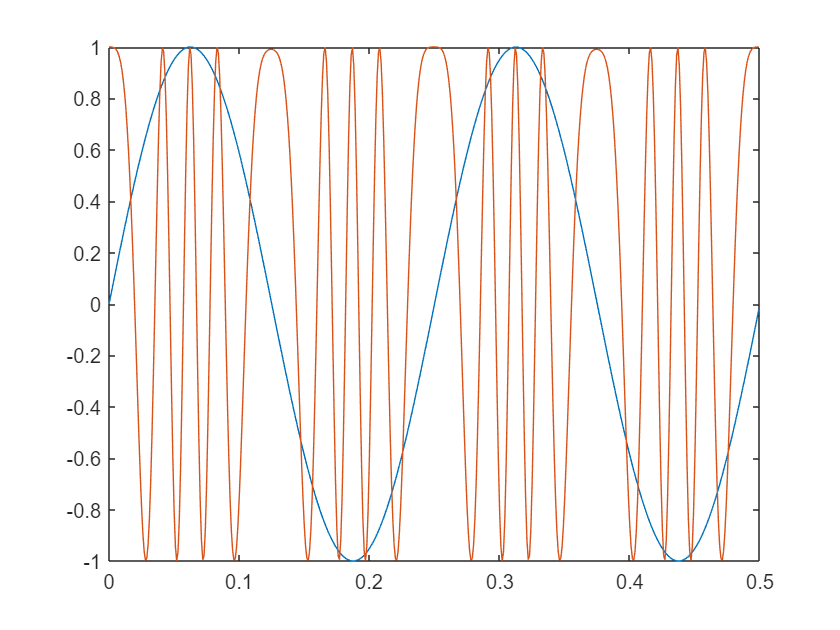

fs = 1e3;  % Sample rate (Hz)
ts = 1/fs; % Sample period (s)
fd = 50;   % Frequency deviation (Hz)
t = (0:ts:0.5-ts)';
x = sin(2*pi*4*t);
fmmodulator = comm.FMModulator( ...
    'SampleRate',fs, ...
    'FrequencyDeviation',fd);
y = fmmodulator(x);
plot(t,[x real(y)])